We import the data from: https://www.kaggle.com/datasets/fedesoriano/body-fat-prediction-dataset?resource=download

% Import the data
opts = detectImportOptions('bodyfat.csv'); 
data = readtable('bodyfat.csv', opts);

We keep only the columns for age, weight, height.

% Select the necessary columns
data = data(:, [2, 3, 4, 5]);
disp(data);

    BodyFat    Age    Weight    Height
    _______    ___    ______    ______

     12.3      23     154.25    67.75 
      6.1      22     173.25    72.25 
     25.3      22        154    66.25 
     10.4      26     184.75    72.25 
     28.7      24     184.25    71.25 
     20.9      24     210.25    74.75 
     19.2      26        181    69.75 
     12.4      25        176     72.5 
      4.1      25        191       74 
     11.7      23     198.25     73.5 
      7.1      26     186.25     74.5 
      7.8      27        216       76 
     20.8      32      180.5     69.5 
     21.2      30     205.25    71.25 
     22.1      35     187.75     69.5 
     20.9      35     162.75       66 
       29      34     195.75       71 
     22.9      32     209.25       71 
       16      28     183.75    67.75 
     16.5      33     211.75     73.5 
     

We conver imperial to metric and lbs to kg

data.Weight = lbsToKg(data.Weight) ; % lbs to kg
data.Height = imperialToMetric(data.Height); % inches to meters
disp(data);

    BodyFat    Age    Weight    Height
    _______    ___    ______    ______

     12.3      23     69.967    172.09
      6.1      22     78.585    183.52
     25.3      22     69.853    168.28
     10.4      26     83.801    183.52
     28.7      24     83.574    180.97
     20.9      24     95.368    189.87
     19.2      26       82.1    177.16
     12.4      25     79.832    184.15
      4.1      25     86.636    187.96
     11.7      23     89.925    186.69
      7.1      26     84.482    189.23
      7.8      27     97.976    193.04
     20.8      32     81.873    176.53
     21.2      30       93.1    180.97
     22.1      35     85.162    176.53
     20.9      35     73.822    167.64
       29      34     88.791    180.34
     22.9      32     94.914    180.34
       16      28     83.348    172.09
     16.5      33     96.048    186.69
     

`We split the data into inputs and target`

inputs = data(:, 2:end);
target = data(:, 1);

`Convert the table to array`

inputs = table2array(inputs);
target = table2array(target);

`Split the data into training and test sets`

cv = cvpartition(size(data,1),'HoldOut',0.3);
idx = cv.test;
% Train
XTrain = inputs(~idx,:);
YTrain = target(~idx,:);
% Test
XTest = inputs(idx,:);
YTest = target(idx,:);

`Normalize the inputs`

mu = mean(XTrain);
sig = std(XTrain);
XTrain = (XTrain - mu) ./ sig;
XTest = (XTest - mu) ./ sig;

`Define the layers of the network`

`We use the Wide Residual Neural Network technique in a custum model of ours:`

layers = [ ...
    featureInputLayer(size(XTrain,2))
    fullyConnectedLayer(30)
    reluLayer
    fullyConnectedLayer(300)
    reluLayer
    fullyConnectedLayer(1000)
    reluLayer
    fullyConnectedLayer(1500)
    reluLayer
    fullyConnectedLayer(100)
    reluLayer
    fullyConnectedLayer(1)
    regressionLayer];

`Define the training options`

options = trainingOptions('adam', ...
    'MaxEpochs',1000, ...
    'MiniBatchSize',64, ...
    'InitialLearnRate',0.01, ...
    'Shuffle','every-epoch', ...
    'ValidationData',{XTest,YTest}, ...
    'Plots','training-progress', ...
    'Verbose',false);

`Train the network`

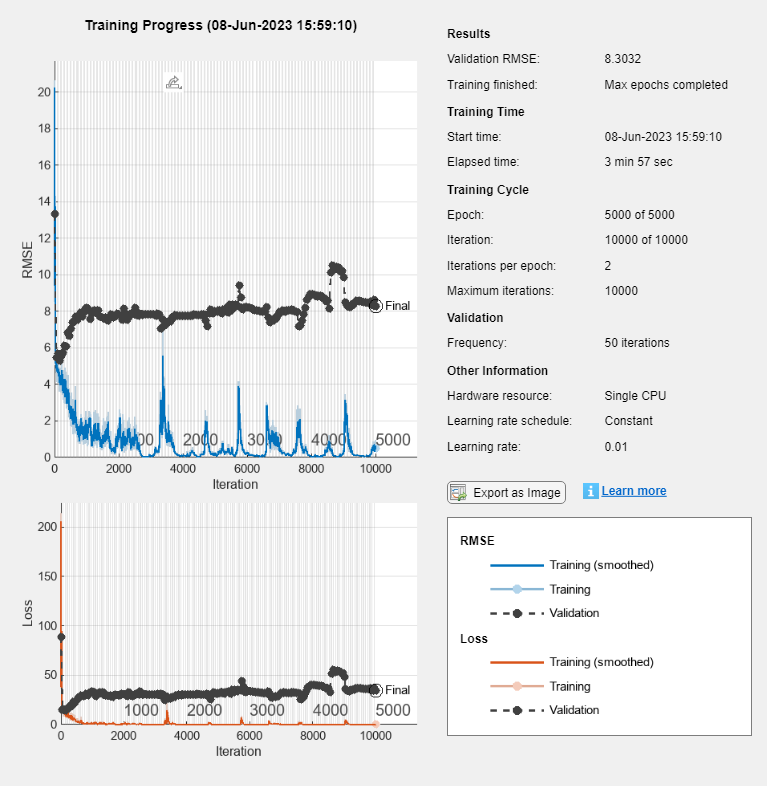

net = trainNetwork(XTrain,YTrain,layers,options);

`Test the network`

YPred = predict(net,XTest);

`Evaluate the performance`

performance = sqrt(mean((YPred-YTest).^2))

performance = single
8.3032

`Test with our own data:`

% Load JSON file
jsonData = fileread('C:\Users\Administrator\Documents\MATLAB\RandomName1442\RandomName1442_user_data.json');
userData = jsondecode(jsonData);

% Extract necessary data
userInput = [userData.age, userData.weight userData.height];

% Use the trained model to make a prediction
userBodyFat = predict(net, userInput);

% Display the result
disp(['The estimated body fat for ', userData.name, ' is ', num2str(userBodyFat), '%.']);

The estimated body fat for RandomName1442 is 404.8851%.


`Visualize the data`

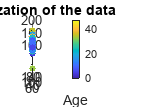

figure
scatter3(data.Age, data.Weight, data.Height, 15, data.BodyFat, 'filled')
colorbar
xlabel('Age')
ylabel('Weight')
zlabel('Height')
title('Visualization of the data')

Calculate some metrics:

% Define a tolerance for the prediction error
tolerance = 0.05; % 5%

% Calculate the absolute percentage error
percentageError = abs((YPred - YTest) ./ YTest);

% Calculate the "accuracy"
accuracy = mean(percentageError <= tolerance);

% Display the "accuracy"
disp(['The "accuracy" of the model is ', num2str(accuracy * 100), '%.']);

The "accuracy" of the model is 8%.


Use the functions to calculate bmi and Fat Free Mass Index of the individual:

disp(['The BMI of the User ' userData.name  ' is ', num2str(calculate_bmi(userData.weight, userData.height))]);

The BMI of the User RandomName1442 is 0.00505


disp(['The Fat Free Mass Index of the User ' userData.name  ' is ', num2str(calculate_ffmi(userData.weight, userData.height,userBodyFat))]);

The Fat Free Mass Index of the User RandomName1442 is -0.015397


We want to be able to use the model from .m scripts. Save the model:

% Save the trained network and normalization parameters
save('trainedModel_bodyfat_prediction.mat', 'net', 'mu', 'sig');

The model due to lack of data and training time has a really small accuracy of 8%

The current limitaions of our work mean that the model may even produce negative values.